1. Use Matlab’s integral2 function to evaluate the following integrals.

        

        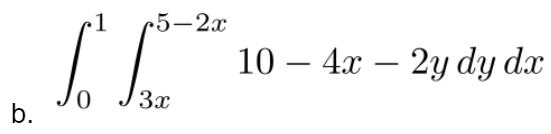

disp('------------------------------------ Q1 --------------------------------------------')

------------------------------------ Q1 --------------------------------------------


f = @(x, y) x.^2 - 3.*y.^2 + x.*y.^3;
area = integral2(f, 0, 4, -2, 2);
disp('a.')

a.


disp(area)

   21.3333




f = @(x, y) 10 - 4*x - 2*y;
area = integral2(f, 0, 1, @(x) 3*x, @(x)5-2*x);

disp('b.')

b.


disp(area)

    8.3333



2. Use Matlab’s integral3 function to evaluate the following integrals.

        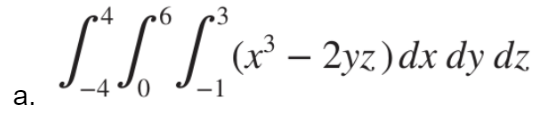

        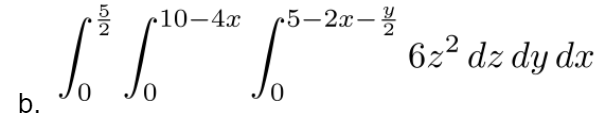

disp('------------------------------------ Q2 --------------------------------------------')

------------------------------------ Q2 --------------------------------------------


f = @(x, y, z) x.^3 - 2.*y.*z;
area = integral3(f, -1, 3, 0, 6, -4, 4)

area = 960

disp('a.')

a.


disp(area)

   960




f = @(x, y, z) 6*z.^2;
area = integral3(f, 0, 5/2, 0, @(x) 10-4*x, 0, @(x, y) 5 - 2*x - y/2);
disp('b.')

b.


disp(area)

  312.5000



3. Apply Monte-Carlo integration to the triple integral in 2a using sample points from 1 to 1000. Make a plot with the number of sample points on the horizontal axis and the integral estimate on the vertical axis.

This answer depends on your random numbers which are generated at runtime. Using Matlab’s basic rand() function can generate different results such as the ones shown below:

disp('------------------------------------ Q3 --------------------------------------------')

------------------------------------ Q3 --------------------------------------------


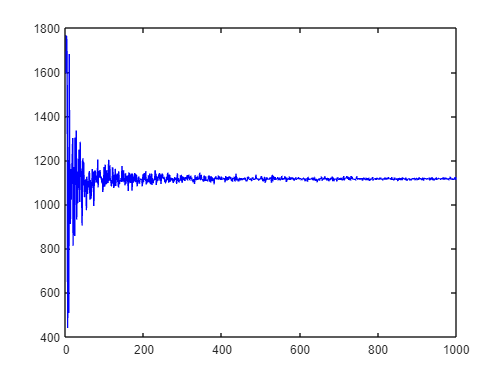

% Step 1: Setup Function to apply random sampling | Slides 40
% From last problem
func = @(x,y,z) x.^3 - 2.*y.*z;  
n = 1000;
xmin = -1;
xmax = 3;
x = xmin + rand(1, n) * (xmax-xmin);

ymin = 0;
ymax = 6;
y = ymin+rand(1, n) * (ymax-ymin);

zmin = -4;
zmax = 4;
z = zmin+rand(1, n) * (zmax-zmin);

% Step 2: Calculate the estimated integral value
A = func(x,y,z) .* ( (xmax-xmin) * (ymax-ymin) * (zmax-zmin) );  % กว้าง * ยาว * สูง

% Step 3: Calculate the avg. of A for each n
avg = zeros(1,n);
for i=1:n
    avg(1,i) = A(i);
    avg(1,i) = sum(avg) / i;
end

% Step 4: Plot graph
plot(1:n, avg, 'b-');

mean(avg);
f = @(x,y) x.^2 - 3.*y.^2 + x.*y.^3;
myans = MonteCarloIntegration(0,4,-2,2,f,0.00001);  % MonteCarlo2Variable

Maximum number of iterations reached. Result may be inaccurate.


disp(myans)

  238.6073



5. Write a function file that performs **Romberg integration** to the desired accuracy. You may use the Matlab built-in function trapz or your own trapezium rule function to calculate the approximation at each step size. The inputs should be the function you wish to integrate, the start and end points, and the desired accuracy (use estimated accuracy).

disp('------------------------------------ Q5 --------------------------------------------')

------------------------------------ Q5 --------------------------------------------


func = @(z) 200 .* (z ./ (5+z)) .* exp((-2.*z) / 30);
real_sol = integral(func, 0, 30);
romberg_sol = romberg(func, 0, 30, 0.5);

error less than the tolerance. STOP!


disp(real_sol);

   1.4806e+03



disp(romberg_sol);

   1.4330e+03



## Functions

function [monte_int] = MonteCarloIntegration(max_x, min_x, max_y, min_y, func, tol)
    
    % domain comes from the integral area.

    n = 0;
    error = 5000;
    samples = 100000;
    x = (max_x - min_x).*rand(samples,1)+min_x;
    y = (max_y - min_y).*rand(samples,1)+min_y;
    value = [];
    
    while n < samples || tol < error
        n = n+1;
        value(end + 1) = (max_x-min_x).*(max_y-min_y)*func(x(n),y(n));
        if length(value) >= 2
            error = value(end) - value(end-1);
        end
        if length(value) == n
            disp('Maximum number of iterations reached. Result may be inaccurate.')
            break
        end
    end
    monte_int = sum(value)/n;
end


function A = romberg(func, a, b, tol)
    i_max = 1000;
    n = 1;
    i(1,1) = trapezium(func, a, b, n);          % เพราะ Romberg พื้นฐานมาจาก Richardson Extrapolation และ Richard ก็อิงมาจาก Trapz Rule อีกที
    j = 0;
    while j < i_max
        j = j + 1;
        n = 2^j;
        I(j+1, 1) = trapezium(func, a, b, n);
        for k=2:j+1
            jj = 2+j-k;
            I(jj,k) = ( ((4^(k-1)) * I(j+1 - (k-2), k-1)) - I(j- (k-2), k-1) )/ ((4^(k-1)) -1) ;% Romberg formula.
        end
        ea = abs((I(1, k) - I(2, k-1))/ I(1,k) ) * 100  ;        % Approximate percentage error.
        if ea < tol               % If statement that breaks the loop if the error is less than the tolerance.
            disp('error less than the tolerance. STOP!')
            break
        end
    end
    A = I(jj,k);                   % Final output.
    if j == i_max                  % If maximum iterations are reached display a warning to the user.
        disp('max iteration reached')
    end
end

function area = trapezium( f, a, b, n )
%{
Implements the composite trapezium rule:
A = (h/2)*(f(x0)+2*f(x1)+2*f(x2)+...+f(xn))
%}
format rational
% Step size
h = (b - a)/ n ;

format default
% x-values at which to evaluate function
x = a : h : b ;

% Vectorised formula for integral
area = (h/2) * ( f(a) + (2 * sum( f(x(2:end-1)) )) + f(b)) ;
end